# Array Indexing

In MATLAB®, there are three primary approaches to accessing array elements based on their location (index) in the array. These approaches are indexing by position, linear indexing, and logical indexing. You can also use mixed indexing by combining both positional and logical indexing.

## Indexing with Element Positions

The most common approach is to explicitly specify the indices of the elements. For example, to access a single element of a matrix, specify the row number followed by the column number of the element. 

A = [1 2 3 4; 5 6 7 8; 9 10 11 12; 13 14 15 16]
e = A(3,2)

`e` is the element in the 3,2 position (third row, second column) of `A`. 

You can also reference multiple elements at a time by specifying their indices in a vector. For example, access the first and third elements of the second row of `A`.

r = A(2,[1 3])

To access elements in a range of rows or columns, use the [colon](docid:matlab_ref#bvg1wnp) operator. For example, access the elements in the first through third rows and the second through fourth columns of `A`.

r = A(1:3,2:4)

An alternative way to access those elements is to use the keyword `end` to represent the last column. This approach lets you specify the last column without knowing exactly how many columns are in `A`.

r = A(1:3,2:end)

If you want to access all of the rows or columns, use the colon operator by itself. For example, return the entire third row of `A`.

r = A(3,:)

You can also access the second-to-last column of `A` by using the colon operator and the `end` keyword.

r = A(:,end-1)

In general, you can use indexing to access elements of any array in MATLAB regardless of its data type or dimensions. For example, directly access a column of a [`datetime`](docid:matlab_ref#buhzxmk-1) array.

t = [datetime(2018,1:5,1); datetime(2019,1:5,1)]
march1 = t(:,3)

For higher-dimensional arrays, expand the syntax to match the array dimensions. Consider a random 3-by-3-by-3 numeric array. Access the element in the second row, third column, and first sheet of the array.

A = rand(3,3,3);
e = A(2,3,1)

For more information on working with multidimensional arrays, see [Multidimensional Arrays](docid:matlab_math#f1-86528).

## Indexing with Single Index

Another approach to accessing elements of an array is to use only a single index, regardless of the size or dimensions of the array. This approach is known as *linear indexing*. While MATLAB displays arrays according to their defined sizes and shapes, they are actually stored in memory column by column, proceeding from left to right. A good way to visualize this concept is with a matrix. While the following array is displayed as a 3-by-3 matrix, MATLAB stores it as a single column made up of the columns of `A` appended one after the other. The stored vector contains the sequence of elements `12`, `45`, `33`, `36`, `29`, `25`, `91`, `48`, `11`, and can be displayed using a single colon.

A = [12 36 91; 45 29 48; 33 25 11]
Alinear = A(:)

For example, the 3,2 element of `A` is `25`, and you can access it using the syntax `A(3,2)`. You can also access this element using the syntax `A(6)`, since `25` is the sixth element of the stored vector sequence.

e = A(3,2)
elinear = A(6)

While linear indexing can be less intuitive visually, it can be powerful for performing certain computations that are not dependent on the size or shape of the array. For example, you can easily sum all of the elements of `A` without having to provide a second argument to the `sum` function. 

s = sum(A(:))

The [`sub2ind`](docid:matlab_ref#bsge9r6) and [`ind2sub`](docid:matlab_ref#f86-998447) functions help to convert between original array indices and their linear version. For example, compute the linear index of the 3,2 element of `A`.

linearidx = sub2ind(size(A),3,2)

Convert the linear index back to its row and column form.

[row,col] = ind2sub(size(A),6)

## Indexing with Logical Values

Using true and false logical indicators is another useful approach to index into arrays, particularly when working with conditional statements. For example, suppose you want to know if the elements of a matrix `A` are less than the corresponding elements of another matrix `B`. The less-than operator returns a logical array whose elements are `1` where an element in `A` is smaller than the corresponding element in `B`.

A = [1 2 6; 4 3 6]
B = [0 3 7; 3 7 5]
ind = A < B

Now that you know the locations of the elements meeting the condition, you can inspect the individual values using `ind` as the index array. MATLAB matches the locations of the value 1 in `ind` to the corresponding elements of `A` and `B`, and lists their values in a column vector.

Avals = A(ind)
Bvals = B(ind)

 MATLAB "`is`" functions also return logical arrays that indicate which elements of the input meet a certain condition. For example, check which elements of a string vector are missing using the [`ismissing`](docid:matlab_ref#bty8cec-1) function.

str = ["A" "B" missing "D" "E" missing];
ind = ismissing(str)

Suppose you want to find the values of the elements that are *not* missing. Use the `~` operator with the index vector `ind` to do this.

strvals = str(~ind)

For more examples using logical indexing, see [Find Array Elements that Meet a Condition](docid:matlab_prog#bt_cq89).

## Mixed Indexing with Logical Values and Element Positions

You can also use a combination of positional and logical indexing to access array elements.

For example, create a 5-by-5 matrix.

A = magic(5)

Suppose you want to select the elements of A that are located in rows with prime indices and in columns with indices 2, 3, and 4.

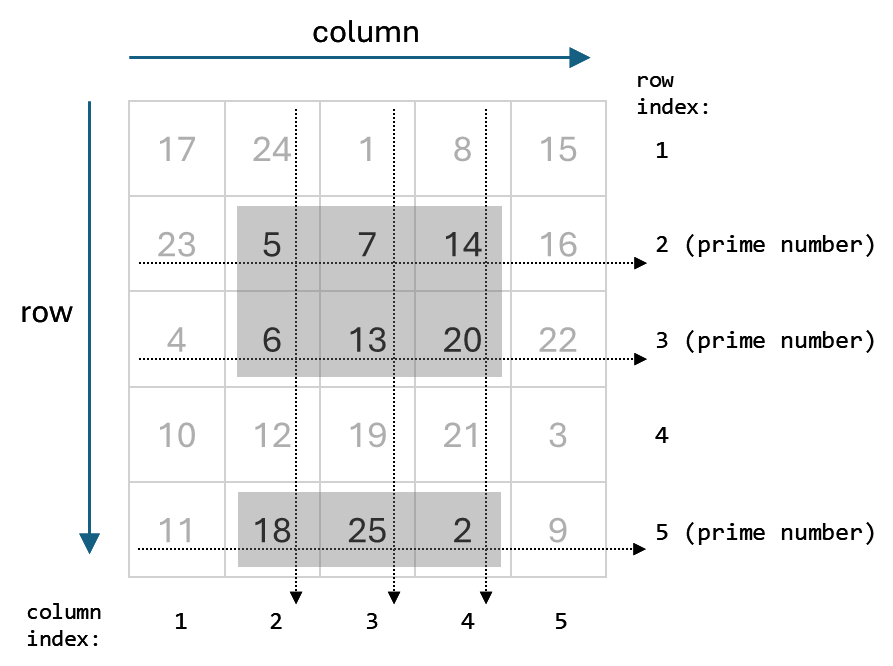

To do this, create a vector `B` that represents the indices of the rows in `A`.

B = (1:size(A,1))

Use the `isprime` function to determine which elements in `B` are prime. The result is a logical array that you can use to index into the rows of `A`.

rows = isprime(B)

Next, define the columns you want to select, which are located in positions 2 to 4.

cols = 2:4

Use logical indexing to select the rows of `A` located at prime number positions, as defined by `rows`. Then, use indexing by position to select the columns of `A` ranging from positions 2 to 4, as defined by `cols`.

A(rows,cols)

*Copyright 2018-2024 The MathWorks, Inc.*